# **Esercitazione 1 - ECG**

Obiettivo 1: implementare una funzione per identificare i picchi R all'interno di ciascun segnale.

Caricamento del dato nel workspace utilizzando la funzione `load().`

load("data.mat")

Suddivisione del segnale in finestre continue con stessa lunghezza pari a pochi secondi (scelti arbitrareamente) e quindi rimozione del trend lineare tramite l'uso della funzione detrend.

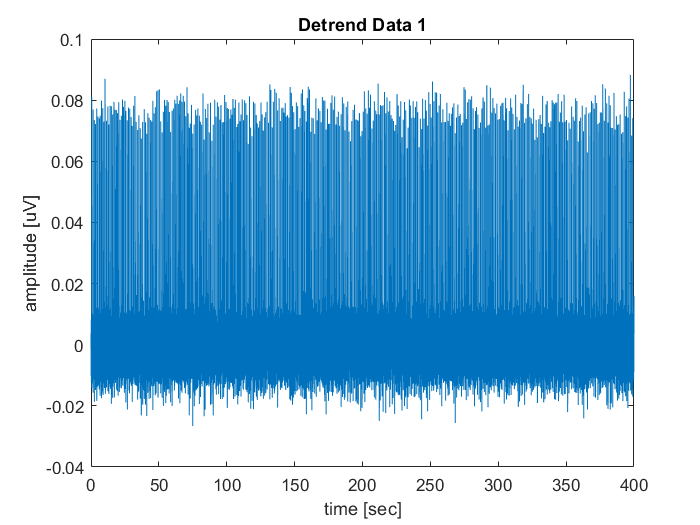

%lunghezza k delle finestre 
k = 1; % [s]

%suddivisione dei segnali
data1 = reshape(data1,fs*k,[]);
data1NoTrend = detrend(data1);

data2 = reshape(data2,fs*k,[]);
data2NoTrend = detrend(data2);

%visualizzazione del risultato ottenuto
data1NoTrend = data1NoTrend(:);

data2NoTrend = data2NoTrend(:);

drawPlot(time, data1NoTrend, 'Detrend Data 1')

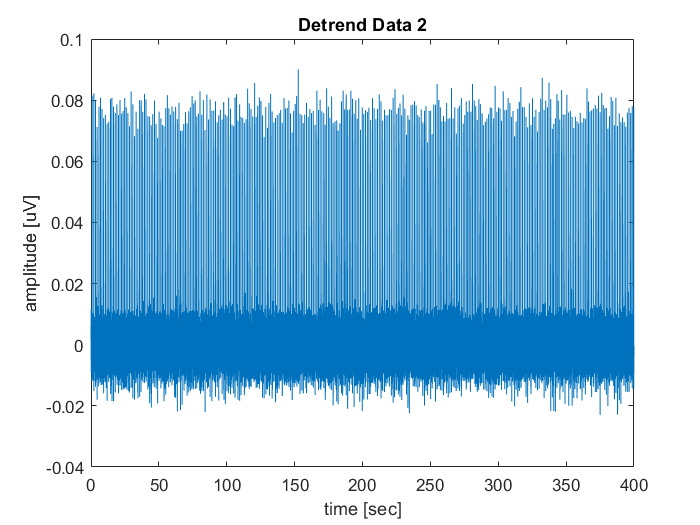

drawPlot(time, data2NoTrend, 'Detrend Data 2')

Utilizzo delle funzioni find_ecg_peaks e find_thr per l'identificazione dei picchi R.

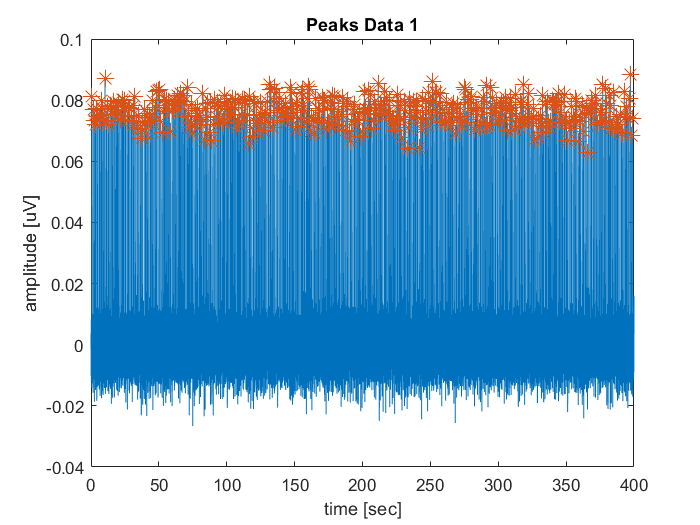

[values1, MaxInd1] = find_ecg_peaks(data1NoTrend, fs ,6);

drawPlot(time, data1NoTrend, 'Peaks Data 1')

hold on
plot(MaxInd1,values1,'*','MarkerSize',10)
hold off

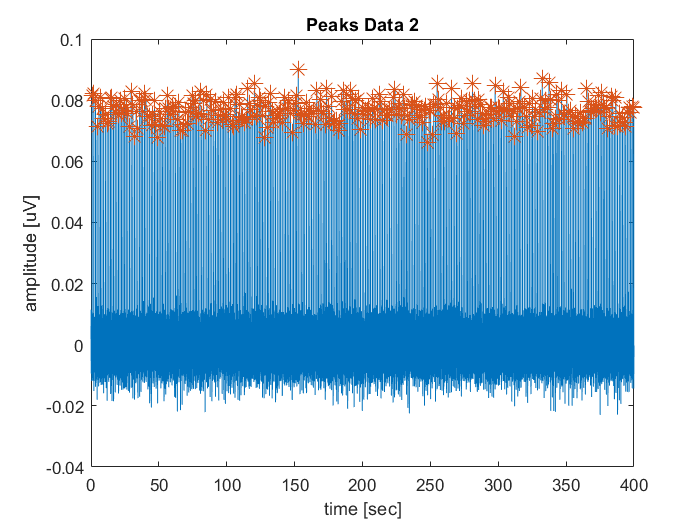


[values1, MaxInd2] = find_ecg_peaks(data2NoTrend,fs,6);

drawPlot(time, data2NoTrend, 'Peaks Data 2')

hold on
plot(MaxInd2,values1,'*','MarkerSize',10)
hold off

Obiettivo 2: implementare una funzione compute_heart_rate per stimare la frequenza del battito cardiaco.

heart_rate1 = compute_heart_rate ( MaxInd1,data1NoTrend)

heart_rate1 = 64.9500

heart_rate2 = compute_heart_rate ( MaxInd2,data2NoTrend)

heart_rate2 = 49.8000

Obiettivo 3: implementare una funzione per il calcolo della durata del complesso QRS e per la visualizzazione del complesso QRS medio.

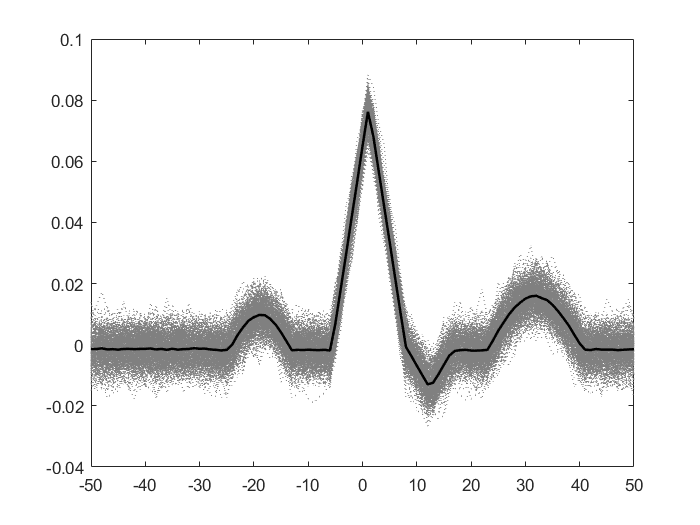

% calcolo distanza tra picchi R successivi
dist_RR1=MaxInd1(2:end)-MaxInd1(1:end-1);
dist_RR2=MaxInd2(2:end)-MaxInd2(1:end-1);

%calcolo distanza media tra picchi R successivi per il tracciato 1 
mean_dist1=round(mean(dist_RR1));

%considero una distanza inferiore
interval1= mean_dist1/20 ;

%costruisco l'asse del tempo per il tracciato 1 
assex=linspace(  - 1000 * interval1 , 1000* interval1 ,  1000 * 2 * interval1 +1);

%matrice che contiene i sigoli battiti del tracciato 1
heartbeats_1=zeros(length(MaxInd1), fs*interval1*2 +1);

figure
for j=1:length(MaxInd1)
    heartbeats_1(j,:)=data1NoTrend( fs*(MaxInd1(j)-interval1) : fs*(MaxInd1(j)+interval1));
    
    plot(  assex , heartbeats_1(j,:) , ":" , "Color",'#808080')
    hold on
end

%tracciato complesso medio
mean_hb1=mean(heartbeats_1);

hold on
plot( assex , mean_hb1, "k", "LineWidth", 1.5);
hold off


%calcolo durata del complesso qrs
qrs_medio1 = mean (qrs_duration (heartbeats_1 , fs))

qrs_medio1 = 17.1339

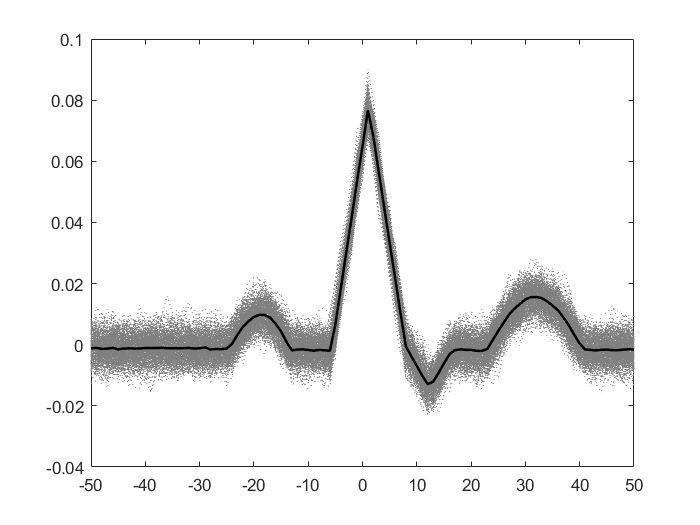


%calcolo distanza media tra picchi R successivi per il tracciato 2
mean_dist2=round(mean(dist_RR2));

%considero una distanza inferiore
interval2=mean_dist2/20;

%costruisco l'asse per il tracciato 2
assex=linspace( -1000 * interval2 ,  1000 * interval2 , 1000* 2*interval2 + 1);

%matrice che contiene i singoli battiti del tracciato 2
heartbeats_2=zeros(length(MaxInd2), fs* interval2*2 +1);

figure
for j=1:length(MaxInd2)
    heartbeats_2(j,:)=data2NoTrend(fs*(MaxInd2(j)-interval2) : fs*(MaxInd2(j)+interval2));
    
    plot( assex, heartbeats_2(j,:) , ":" , "Color",'#808080')
    hold on
end

mean_hb2=mean(heartbeats_2 );

hold on
plot(assex, mean_hb2, "k", "LineWidth", 1.5);
hold off


%calcolo durata complesso QRS
qrs_medio2= mean (qrs_duration (heartbeats_2, fs))

qrs_medio2 = 17.2470

Obiettivo 4: implementare una funzione per la stima della densità di probabilità delle variabili derivate da ECG per descrivere i ritmi cardiaci.

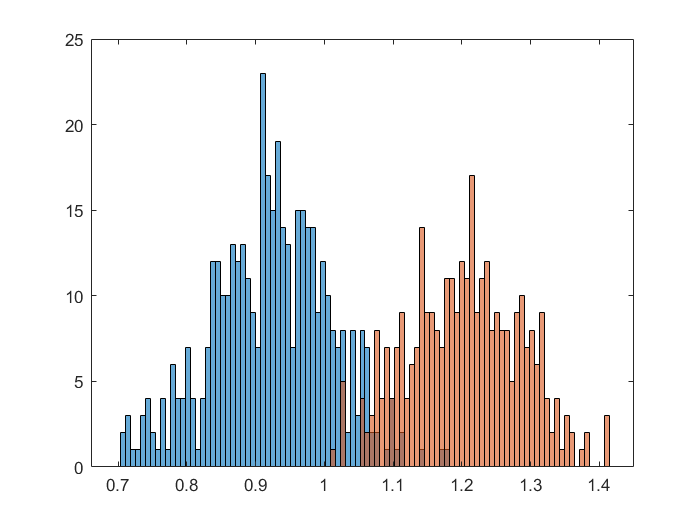

n_binsRR = 100; 
confronto_PDF(dist_RR1 , dist_RR2 , n_binsRR)

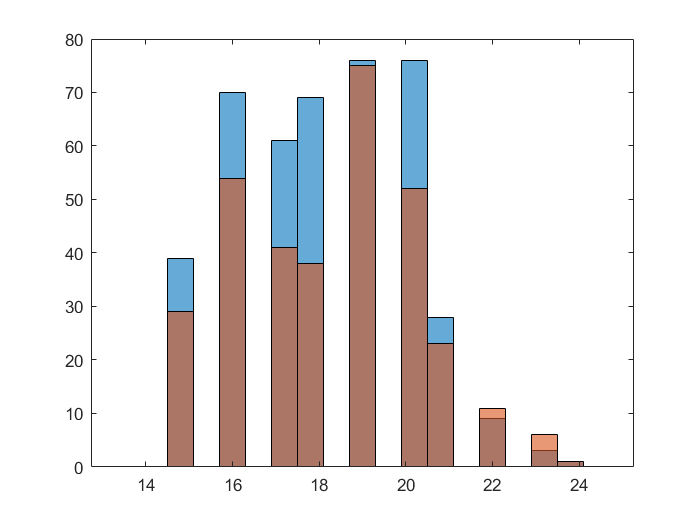


n_binsQRS = 20; 
QRS1 = ( qrs_duration (heartbeats_1 , fs) )';
QRS2 = ( qrs_duration (heartbeats_2 , fs) )';
confronto_PDF(QRS1 , QRS2 , n_binsQRS)